# **Robo: Bridge of Doom Challenge**

### **Authors: Berwin Lan and Cara Mulrooney**

## **Exercise 21.1**

1. For the Bridge of Doom, plot the parametric curve that defines the centerline of the bridge.

2. On the same figure, plot the unit tangent and unit normal vectors at several points along the curve. You should have starter code to help with this in the Robo Homework 1 assignment.

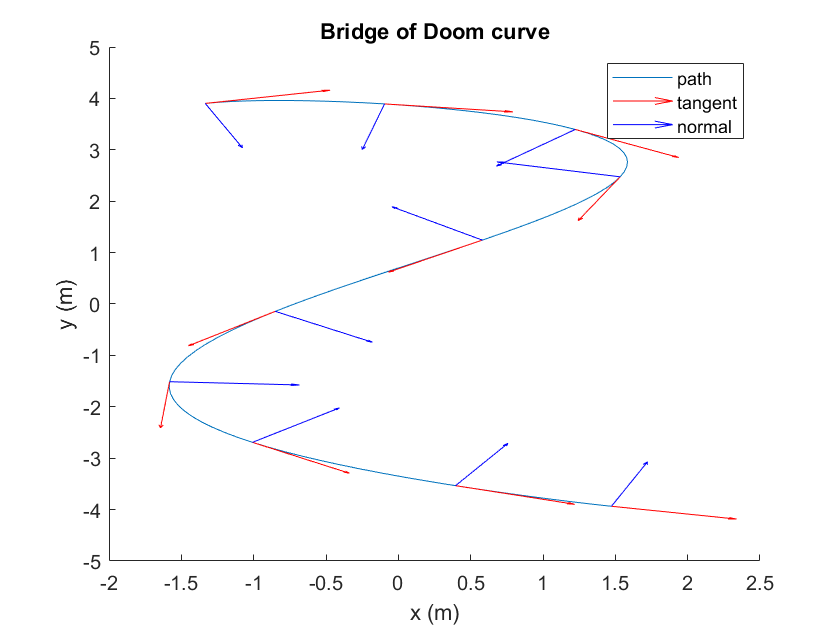

clc, clear all;

% The position equations
t = linspace(0, 3.2);   % seconds
ri = 4 * 0.396*cos(2.65*(t + 1.4)); % x-component of vector
rj = 4 * 0.99*sin(t + 1.4);         % y-component of vector
rk = 0 * t;                         % z-component of vector

% Plotting the position curve
clf; hold on;
plot3(ri, rj, rk);
title("Bridge of Doom curve"); xlabel("x (m)"); ylabel("y (m)");

% Equations
syms u 
ri = 4 * 0.396*cos(2.65*(u + 1.4)); % x-component of vector
rj = 4 * 0.99*sin(u + 1.4);         % y-component of vector
rk = 0 * u;                         % z-component of vector
r = [ri, rj, rk];
u_num = linspace(0, 3.2, 10); % define a set of evenly spaced points between 0 and 3.2

% Find tangent vector
dr = diff(r, u);
T_hat=simplify(dr / norm(dr));

% Find normal vector
dT_hat=diff(T_hat,u);
N_hat=simplify(dT_hat / norm(dT_hat));

% Substitute values into equations
for n=1:length(u_num)
    r_num(n,:) = double(subs(r, u, u_num(:,n)));
    T_hat_num(n,:) = double(subs(T_hat, u, u_num(:,n)));
    N_hat_num(n,:) = double(subs(N_hat, u, u_num(:,n)));
    
    % Plot vectors
    hold on
    quiver3(r_num(n,1), r_num(n,2), r_num(n,3), T_hat_num(n,1), T_hat_num(n,2), T_hat_num(n,3), 'r') % plot the unit tangent
    quiver3(r_num(n,1), r_num(n,2), r_num(n,3), N_hat_num(n,1), N_hat_num(n,2), T_hat_num(n,3), 'b') % plot the unit normal
    drawnow % Force the graphic to update as it goes
end
legend({"path", "tangent", "normal"})

Brent advice for verification: when you plot pos based on v it graphs correctly (overlay neato pos points on actual path of BoD)

## **Exercise 21.2**

**Compute and plot the linear speed and angular velocity as a function of time. (Reference code: Ex 18.2)**

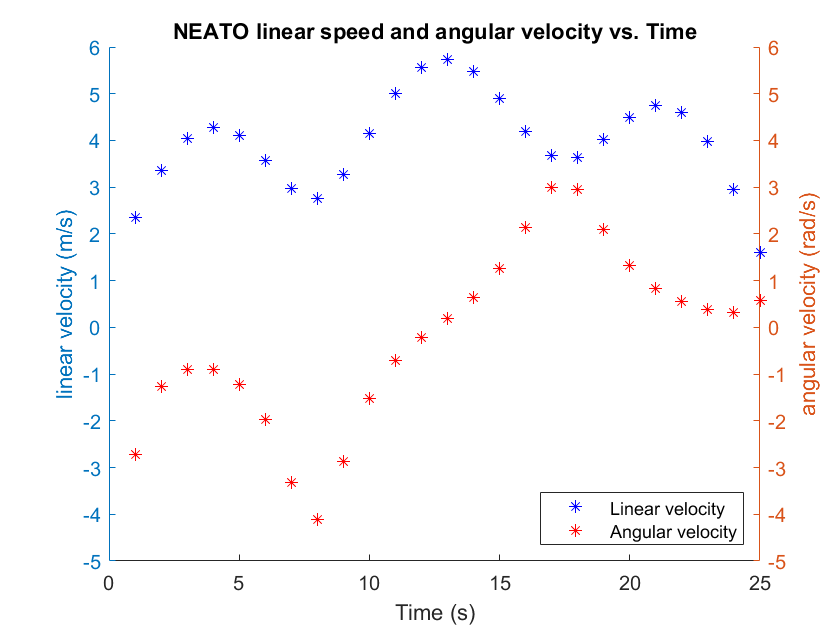

% Find angular velocity
omega = simplify(cross(T_hat, dT_hat));

% Find linear speed
speed = simplify(norm(dr)); % m/s, first derivative of position vector

% Plotting
u_num = linspace(0, 3.2, 25); % define a set of evenly spaced points between 0 and 3.2

% Initialize time, speed, and omega vectors
clf; figure();
u_values = [];
speed_values = [];
omega_values = [];

% Calculate values for speed and omega
for n=1:length(u_num)
    speed_plot = double(subs(speed, u, u_num(:,n)));
    omega_plot = double(subs(omega, u, u_num(:,n)));
    
    omega_khat = omega_plot(1,3);
    
    u_values(1,n) = n;
    speed_values(1,n) = speed_plot;
    omega_values(1,n) = omega_khat;
end

% Plot vectors
hold on
yyaxis left;
plot(u_values, speed_values, "b*", "DisplayName", "Linear velocity");
yyaxis right;
plot(u_values, omega_values, "r*", "DisplayName", "Angular velocity");
legend("Location", "southeast");
xlabel("Time (s)"); title("NEATO linear speed and angular velocity vs. Time");
yyaxis left; ylabel("linear velocity (m/s)"); ylim([-5 6])
yyaxis right; ylabel("angular velocity (rad/s)"); ylim([-5 6])

## **Exercise 21.3**

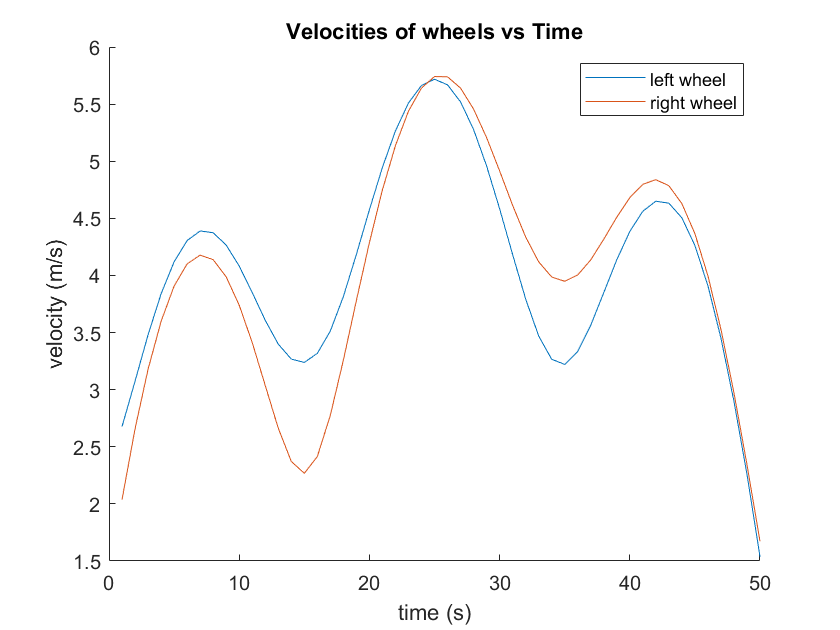

d_num = 0.235;  % m
V_left = simplify(speed - omega(1,3) * d_num / 2);
V_right = simplify(speed + omega(1,3) * d_num / 2);

% Plotting
u_num = linspace(0, 3.2, 50); % define a set of evenly spaced points between 0 and 3.2

% Initialize time, speed, and omega vectors
clf; figure();
u_values = [];
left_values = [];
right_values = [];

% Calculate values for speed and omega
for n=1:length(u_num)
    u_values(1,n) = n;
    left_values(1,n) = double(subs(V_left, u, u_num(:,n)));
    right_values(1,n) = double(subs(V_right, u, u_num(:,n)));
end

clf; figure(); hold on;
plot(u_values, left_values, "DisplayName", "left wheel");
plot(u_values, right_values, "DisplayName", "right wheel");
title("Velocities of wheels vs Time"); xlabel("time (s)"); ylabel("velocity (m/s)"); legend()

## **Exercise 21.4**

## **Exercise 21.5**

## **Exercise 21.6**

Robo HW 1 Code:

%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms u

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri=4*(0.3960*cos(2.65*(u+1.4)));
rj=4*(-0.99*sin(u+1.4));
rk=0*u;
r=[ri,rj,rk];

%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,t);

Unrecognized function or variable 't'.


%velocity and speed
v=dr
speed=simplify(norm(v))


% we want to add some assumptions so that the algebra simplifies the way it
% should
assume(u,'positive') % u should be positive

%now we can use the simplify function to make things look nice
T_hat=simplify(v/norm(v))

%Next, we want to find the unit normal vector
dT_hat=diff(T_hat,t);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

%The unit binormal vector is found from the cross product of the unit
%tangent and unit normal
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat)

%We can also find the curvature
kappa=norm(dT_hat)/norm(dr);
kappa=simplify(kappa)

%How about the Torsion?
tau=-dot(N_hat,(diff(B_hat,t)/norm(dr)))
L = int((norm(dr)),0,2*pi)

%accelerations
accel=diff(v,t)

aN=simplify(dot(accel,N_hat))
aT=simplify(dot(accel,T_hat))

%angular velocity
w = cross(T_hat,dT_hat);
angular_velocity = simplify(w)

%left and right wheel velocities
d = 0.235; % wheel base
V_L = speed - angular_velocity*(d/2);
V_left_wheel = simplify(V_L)

V_R = speed + angular_velocity*(d/2);
V_right_wheel = simplify(V_R)
